 % Setting up the function

x=linspace(-2,2,100);
y=func(x);

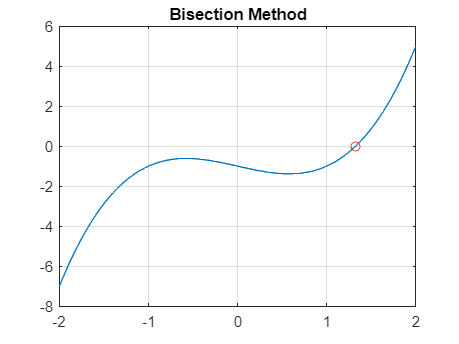

%Bisection method:

plot(x,y)
grid on
hold on

x_b1=-0.5;
x_b2=1.7;

bisec_root=[];
iter_bis_set=[];
iter_bis=0;
x_b=(x_b1+x_b2)/2;
while abs(func(x_b)) > 10^-6
     bisection=func(x_b);
     bisec_root(end+1)=func(x_b);
     x_b=(x_b1+x_b2)/2;
     iter_bis=iter_bis+1;
     iter_bis_set(end+1)=iter_bis;
     if (func(x_b)*func(x_b1)<0)
         x_b2=x_b;
     elseif (func(x_b)*func(x_b2)<0)
         x_b1=x_b;
     elseif func(x_b)==0
         break;
     end
end

plot(x_b,func(x_b),'ro')
title('Bisection Method')
hold off


disp(bisec_root(end))

  -9.1783e-06



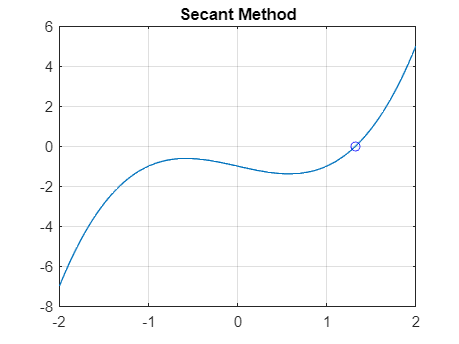

%Secant Method

x_sec_1=1;
x_sec_2=2;

iter_sec_set=[];
iter_sec=0;
sec_roots=[];
while abs(func(x_sec_2))>10^-6
    iter_sec=iter_sec+1;
    iter_sec_set(end+1)=iter_sec;
    x_sec=((x_sec_1*func(x_sec_2))-(x_sec_2*func(x_sec_1)))/(func(x_sec_2)-func(x_sec_1));
    x_sec_1=x_sec_2;
    x_sec_2=x_sec;
    sec_roots(end+1)=func(x_sec_2);
end

plot(x,y)
hold on
plot(x_sec,func(x_sec),'bo')
hold off
title('Secant Method')
grid on


disp(sec_roots(end))

   3.4582e-08



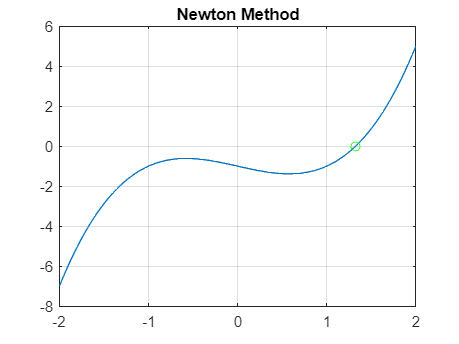

%Newtons Method

x_newt= -1;
iter_newt=1;
iter_newt_set=[];
newt_root=[];
while abs(func(x_newt))>10^-6
    x_newt=x_newt-(func(x_newt)/df(x_newt));
    iter_newt=iter_newt+1;
    iter_newt_set(end+1)=iter_newt;
    newt_root(end+1)=func(x_newt);
end

plot(x,y)
hold on
plot(x_newt,func(x_newt),'go')
hold off
title('Newton Method')
grid on


disp(newt_root(end))

   2.7471e-12



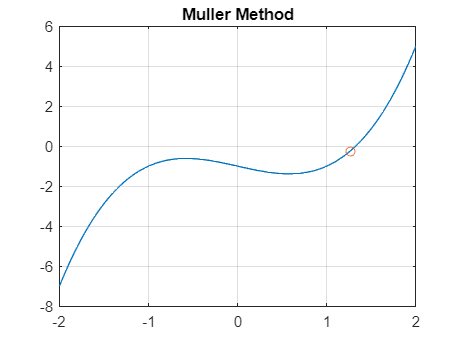

%Muller's method

%set initial guesses:
x_0=0;
x_1=1;
x_2=2;
x0=[];
x1=[];
x2=[];
%initialize x_3 with a non zero number
x_3=100;
x3=[];
iter_mul=0;
iter_mul_set=[];
muller_root=[];
a_values=[];
b_values=[];
c_values=[];
while(abs((x_3-x_2)/x_3)>10^-6)
    
    [a,b,c]=quadratic_coeff([x_0,x_1,x_2],[func(x_0),func(x_1),func(x_2)]);

    x0(end+1)=x_0;
    x1(end+1)=x_1;
    x2(end+1)=x_2;
    a_values(end+1)=a;
    b_values(end+1)=b;
    c_values(end+1)=c;
    
    
    x_3=x_2-(2*c/(b+sign(b)*sqrt(b^2-(4*a*c))));
    x3(end+1)=x_3;

    x_0=x_1;
    x_1=x_2;
    x_2=x_3;

    muller_root(end+1)=func(x_3);
    iter_mul=iter_mul+1;
    iter_mul_set(end+1)=iter_mul;
   
end

saved_values=table(iter_mul_set,x0,x1,x2,x3,a_values,b_values,c_values);

plot(x,y)
hold on
plot(x_3,func(x_3),'o')
hold off
title('Muller Method')
grid on

saved_values

saved_values = 1×8 table
    Var1    Var2    Var3    Var4     Var5     Var6    Var7    Var8
    ____    ____    ____    ____    ______    ____    ____    ____

     1       0       1       2      1.2638     3       9       5  


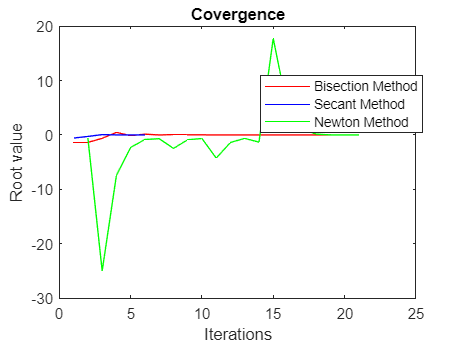

%Convergence Plots

plot(iter_bis_set, bisec_root,'r')
hold on
plot(iter_sec_set, sec_roots,'b')
plot(iter_newt_set,newt_root,'g')
hold off
title('Covergence')
legend('Bisection Method','Secant Method','Newton Method')
legend("Position",[0.60033,0.63037,0.29126,0.13528])
ylabel('Root value')
xlabel('Iterations')

function y=func(x)
    y=x.^3-x-1;
end

function dydx=df(x)
    dydx=3*x.^2-1;
end

function [a,b,c]=quadratic_coeff(x,y)
    c=y(3);
    A=[(x(1)-x(3))^2 x(1)-x(3);(x(2)-x(3))^2 x(2)-x(3)];
    sols=inv(A)*transpose([y(1)-c y(2)-c]);
    a=sols(1);
    b=sols(2);
end